Wdu=M(:,1);%东向风速
Wdv=M(:,2);%北向风速
Wdw=M(:,3);%合风速
Wuv=atan(Wdu./Wdv);%风向与北向夹角
Wdu(Wdu<-9990)=[];
Wdv(Wdv<-9990)=[];
Wdw(Wdw<-9990)=[];
Wuv(Wuv<-9990)=[];

Wdu=roundn(Wdu,-1);
Wdv=roundn(Wdv,-1);
Wdw=roundn(Wdw,-1);
Wuv=roundn(Wuv,-1);

Wdu1 = tabulate(Wdu);%统计数组（x）中元素出现的频率
Wdu2 = array2table(Wdu1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
Wdv1 = tabulate(Wdv);%统计数组（x）中元素出现的频率
Wdv2 = array2table(Wdv1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
Wdw1 = tabulate(Wdw);%统计数组（x）中元素出现的频率
Wdw2 = array2table(Wdw1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
Wuv1 = tabulate(Wuv);%统计数组（x）中元素出现的频率
Wuv2 = array2table(Wuv1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表

figure()
% subplot(1,3,1)
% bar(Wdu2.Value,Wdu2.Count);
% xlabel("Velocity(m/s)");ylabel("Count")
% title("Eastward Velocity of Wind")
% subplot(1,3,2)
% bar(Wdv2.Value,Wdv2.Count);
% xlabel("Velocity(m/s)");ylabel("Count")
% title("Northward Velocity of Wind")
% subplot(1,3,3)
subplot(121)
bar(Wdw2.Value,Wdw2.Count);
xlabel("Velocity (m/s)");ylabel("Count")
title("Compound Velocity of Wind")
% subplot(1,3,4)
% bar(Wuv2.Value,Wuv2.Count);
% xlabel("Degree(rad)");ylabel("Count")
% title("Wind Direction To North")

% figure()
subplot(122)
[f,xi]=ksdensity(Wdw);
plot(xi,f,'r*');
hold on
[mu,sigma]= normfit(Wdw,0.05)

mu = single
7.7979

sigma = single
2.5324

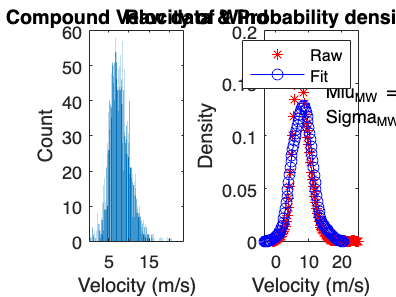

% [mu,sigma,muci,sigmaci]= normfit(data,a);
% data: 原数据
% a :置信度
% mu: 均值
% sigma: 标准差
% muci:1-a 区间内的均值
% sigmaci:1-a 区间内的标准差
TJ=ones(100,1);
LTJ=length(TJ);
N0=normrnd(mu,sigma,1,LTJ);
[f1,xi1]=ksdensity(N0);
plot(xi1,f1,'b-o');
hold off

xlabel('Velocity (m/s)')
ylabel('Density')
legend('Raw','Fit')
title("Raw data & Probability density function")
txt = { ['Miu_{MW} = ' num2str(mu)]; ['Sigma_{MW} = ' num2str(sigma)] };
text(xi(60),f(60)+0.12,txt)